# Lab #6 FIR Filtering of Nasal Air Temperature (Two Weeks)

## Objectives:

- Create a model of input data to provide a repeatable way to test and analyze filters.

- Use fixed point representation scaling to allow faster calculations with better resolution.

- Use what you have learned about datatypes, execution time, and memory usage to optimize filter performance.

- Learn how to create the filter kernel (impulse response) for a moving average filter and a windowed sinc filter.

- Learn how to implement a FIR filter using convolution.

- Learn how to modify a filtering algorithm (datatype, scaling, and length) to work within the limitations of a given digital signal processing chip. 

## Reading

    Review Chapters 14 & 16in Smith.      

    Supplemental Reading -- "Resp Rate greater than 50 per minute as indicator of pneumonia”  

## Intended Learning Outcomes

- Demonstrate filtering of a signal using a FIR filter implemented in a microprocessor.

- Demonstrate the ability to choose appropriate variable datatypes and signal scaling for those datatypes.

- Practice communicating your results and your work in writing

## Lab 6 Arduino Code Base

The codebase for Lab 06 is located in myCourses

### **Overview**

In this lab you will use your temperature sensor to measure nasal airflow temperature. The temperature of the air flowing over the sensor is lower when you breathe in (drawing cool room air across the sensor) and higher when you exhale (pushing air across the sensor that has been warmed by your lungs).  The temperature output will look somewhat sinusoidal.

From the changing temperature signal, it is possible to determine a person’s respiration rate. A respiration rate of over 50 breaths per minute can be an indication of pneumonia. As we know from sampling theory, the sample rate for data collection must be at least twice this frequency to satisfy the Nyquist criteria.

In your data collection system, you will need to collect 256 samples of temperature readings, at a sampling interval of $T_s = 100$ milliseconds. This corresponds to a sampling frequency of 10 Hz.  At this rate the Nyquist frequency is:

####  
$$Nyquist Frequency = F_s/2 = 5Hz$$


This translates to a maximum detectable breathing rate of:

####  
$$Nyquist Frequency = 5Hz = 5 \frac{breaths}{Sec}$$


####  
$$Nyquist Frequency = 5\frac{breaths}{sec}\times60\frac{Sec}{Min}=300\frac{breaths}{Min}$$


Which is much higher than the 50 breaths per minute requirement.  With 256 samples, you will be collecting data over a time period of 25.6 seconds. 

The signal read from the LM61 temperature sensor has quantization noise and analog noise on it. To get a good signal, two filtering steps will be used. First, dithering and over sample averaging is used to get a clean signal from the ADC.  An over-sample rate of 8 will be used.  This process takes about 6.5 milliseconds for each sample average. 

After the 256 samples of temperature data is retrieved from the ADC and averaging process, the samples will be low pass filtered.  You will implement and compare the results of two different Finite Impulse Response (FIR) filters: a moving average (MAV) filter and a windowed SINC filter. Both these FIR filters are implemented using convolution as shown in the figure below.

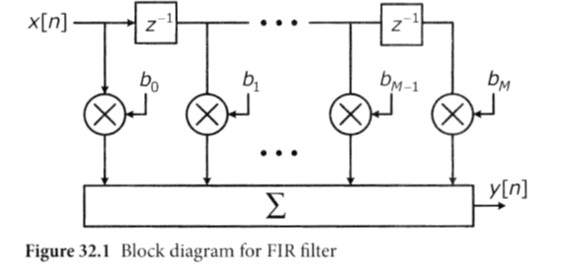

## **Section 1 -- Modeling of Breathing Data**

### **Section Discussion**

In this section you will simulate real breathing data using a file with data already recorded for you.  The simulated breathing data will look sinusoidal in nature with some temperature drift.  You are to create a mathematical model of the temperature data that you gathered by estimating the slope of the linear drift, the intercept of the drift, its sinusoidal frequency and amplitude, and the amount of noise on the signal.  You will use the simulated temperature data from a MATLAB file and compute the model parameters in MATLAB.  Then you will implement the model of this signal using an equation within the Arduino C code.  This model will be used as the input signal for other portions of the lab to provide a consistent signal for testing so that comparisons can be made between filtering operations.

### **Description of the code**

Use the code "CodeBase_Lab06_Section1_2245.ino" from myCourses and paste it into a new Arduino sketch.  In `loop()`, 256 samples of the simulated temperature sensor data are collected and displayed.  Each sample is the average of 8 dithered subsamples from the ADC.  Each sample is converted to the ADC voltage using the equation developed in Lab 2.  Then the voltage values are  converted to temperature in degrees Celsius using the conversion equation from the LM61 data sheet.  This was also done in Lab 2.  The code is already included in the Arduino sketch.

### **Procedure**

***Determine a model of real breathing data from file data.  Perform the steps in MATLAB.  A summary of the steps are repeated below.  Look at the MATLAB code section for the comments about each step.***

1.  Load the file "Real_Breathing_Data.mat" found in myCourses into MATLAB.  This data represents real breathing data at a rate of approximately 30 breaths per minute..  As usual, this will load a variable into the MATLAB workspace named "outData".   The first column of outData is the sample number.  The second column is the readings from the ADC.  Plot your data.  Title and label the plot

2.  Estimate the temperature drift as you have done in other labs using the polyfit function.  Find the driftSlope and the driftIntercept

3.  Remove the drift and plot the signal with the drift removed.

4.  Estimate the period of the breathing rate in samples per cycle (samplesPerCycle).  Estimate this from a graph of the data with the drift removed.  Use the markers on the graph to estimate the number of samples per each cycle.  Remember, this is just an estimate!

5.  Convert the breathing rate from "samplesPerCycle" to breaths per minute using:    bpm = 1/samplesPerCycle * 10 Samples/Sec * 60 Sec/Min.  Create  a variable "bpm".

6.  Estimate the peak amplitude of the temperature variation (tempP).  Estimate this from a graph of the data with the drift removed.  Do this by measuring the peak to peak amplitude and divide that value by two.  Again this is just an estimate.

         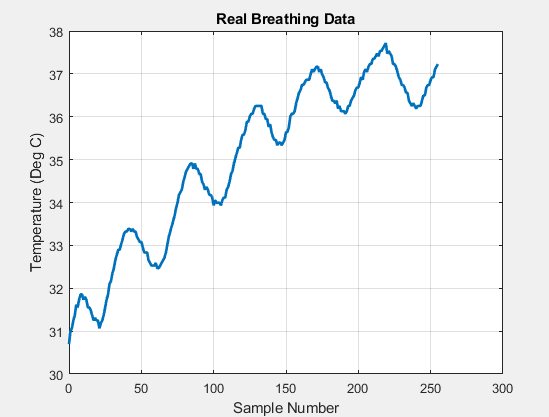

%  Load the breathing data that you recorded or use the example file
%  provided in myCourses

fileName = 'Real_Breathing_Data.mat';
load(fullfile(pwd, fileName));

Error using load
Unable to find file or directory 'C:\Users\cmd3102\Downloads\lab6\Real_Breathing_Data.mat'.

sample = outData(:,1);
temperature = outData(:,2);

%
%  Here is a summary of the steps to follow.  Place your code in the
%  section marked by YOUR SOLUTION
%


%  1.  Plot your data.  Title and label the plot
figure;
plot(sample, temperature, 'b');
xlabel('Sample Number');
ylabel('Temperature (°C)');
title('Recorded Breathing Data');
grid on;


%  YOUR SOLUTION


%  2.  Estimate the temperature drift as you have done in other labs using
%      the polyfit function.  Create two variables "driftSlope" and
%      "driftIntercept"

%  YOUR SOLUTION
p = polyfit(sample, temperature, 1); % Linear fit: p(1)*x + p(2)
driftSlope = p(1);
driftIntercept = p(2);
fprintf('Drift slope: %.4f, Drift intercept: %.4f\n', driftSlope, driftIntercept);



%  3.  Remove the drift and plot the temperature data with the drift removed. 

%  YOUR SOLUTION

drift = driftSlope*sample + driftIntercept;
temperatureNoDrift = temperature - drift;

figure;
plot(sample, temperatureNoDrift, 'r');
xlabel('Sample Number');
ylabel('Temperature (°C)');
title('Temperature Data with Drift Removed');
grid on;


%  4.  Estimate the period of the breathing rate in samples per cycle.
%      Create a variable "samplesPerCycle".  Estimate this from a graph of the data with the drift
%      removed.  Use the markers on the graph to estimate the number of samples 
%      per each cycle.  Remember, this is just an estimate!

%  YOUR SOLUTION
samplesPerCycle = 44;
%  5.  Convert this to breaths per minute using:
%
%      bpm = 1/samplesPerCycle * 10 Samples/Sec * 60 Sec/Min
%
%      Create a variable "bpm"

%  YOUR SOLUTION
samplingRate = 10; % Samples per second
bpm = (1/samplesPerCycle) * samplingRate * 60;
fprintf('Estimated Breathing Rate: %.2f bpm\n', bpm);

%  6.  Estimate the peak amplitude of the sinusoid and create a variable "tempPeak".  Estimate this from the graph of the data with the drift
%      removed.  Do this by measuring the peak to peak amplitude and divide that value by two.  Again this is just an estimate.

%  YOUR SOLUTION

tempPeak = 1.34/2;




***Create a repeatable model of the breathing data in MATLAB***

In the following exercises, you will examine the effects of various filter designs on breathing signals like this.  In order to make meaningful conclusions about comparative filter performance, you will need a repeatable breathing signal.  You will model the breathing signal using an equation that includes a time varying temperature, a temperature drift and noise.

####  
$$T = T_0 +T_{drift}*n+T_{peak}sin(2\pi\times n/(\frac{samples}{cycle}))+T_{noise}$$


Where $T_0$  is the average temperature (**driftIintercept**), $T_{drift}$  is the rate of temperature drift (**driftSlope**), $T_{peak}$ is the peak temperature variation (**tempPeak**), **samplesPerCycle** is the period of the breathing rate,   $T_{noise}$ is uniformly distributed noise with standard deviation (**sigma**) which you will experimentally determine and **n** is the sample number.



%  Create a model of the signal in MATLAB so that you can compare it to the
%  real breathing data.  You can then use these parameter estimates in your C
%  code and again compare to make sure your C code is correct
%
%  The signal model equation uses samplesPerCycle.  The C code will do the
%  conversion from bpm to samplesPerCycle for later convenience
%
%  First create the signal model equation without noise.  This will allow
%  you to check the slope and frequency.  Be sure to create a sample number
%  vector "n" that is the sample number from 0 to 255.  You can use the
%  first column of outData if you wish or create your own vector.
%
%  tempModel = driftIntercept + driftSlope * n + tempPeak*sin( 2*pi*n / samplesPerCycle );
%
%  Plot the tempeature model and the real breathing data on the same graph.
%
%  There may be some differences between the real breathing data and the
%  model.  This is ok as long as the main model parameters are close
%  (slope, intercept, bpm and tempPeak).  They do not need to be exact.

%  YOUR SOLUTION
n = (0:255)';

tempModel = driftIntercept + driftSlope * n + tempPeak * sin(2*pi*n / samplesPerCycle);

plot(sample, temperature, 'b', 'DisplayName', 'Real Data'); hold on;
plot(n, tempModel, 'r', 'DisplayName', 'Model (No Noise)');
xlabel('Sample Number');
ylabel('Temperature (°C)');
title('Breathing Data vs Model (No Noise)');
legend;
grid on;

%  Now add noise.  The added noise is a uniform random variable with a STD of 1
%  degC.  It is scaled by your value of sigma, which you will determine
%  empirically (manually adjust the value by eye).  Add the uniform noise to the
%  your model as shown below
%
%  Create a variable that is a uniform random variable with a SD of 1 deg c
%
%  noiseUniform = ( rand(length(n),1) -.5 )/.29;   %  Uniform random  with SD of 1 degC
%
%  This noise value will be scaled by a variable sigma so that you can
%  adjust the noise.  You will adjust this manually to match the real
%  breathing
%
%  noise = sigma * noiseUniform
%
%  The temperature model in MATLAB looks like the equation below:
%
%  tempModel = driftIntercept + driftSlope * n + tempPeak*sin( 2*pi*n / samplesPerCycle) + sigma * noiseUniform;
%
%
%  Plot the model equation on top of the real breathing data for comparison.
%  It doesn't have to be exact, something close will be fine.  Adjust the
%  value of sigma empirically to be close.

%  YOUR SOLUTION

noiseUniform = (rand(length(n),1) - 0.5)/0.29;

sigma = 0.15;  
noise = sigma * noiseUniform;


tempModelNoise = driftIntercept + driftSlope * n + tempPeak * sin(2*pi*n / samplesPerCycle) + noise;


figure;
plot(sample, temperature, 'b', 'DisplayName', 'Real Data'); hold on;
plot(n, tempModelNoise, 'r', 'DisplayName', sprintf('Model with Noise (sigma=%.2f)', sigma));
xlabel('Sample Number');
ylabel('Temperature (°C)');
title('Breathing Data vs Model (With Noise)');
legend;


***Translate your MATLAB model of breathing data to the Arduino C code***

Create a breathing data model in the C code using the  `simulateBreathingDegC() function`.  The simulated breathing data is composed of a constant level (room temperature) plus a ramp (warm up drift) plus a sine wave (breathing temperature cycle) plus a random variable (sensor noise).  Enter the variables that you calculated in MATLAB into the C code.  Run the sketch and plot the simulated breathing output and compare it to the real breathing data and the MATLAB model that you created.

Include the values of your breathing rate model in your lab report.

%
%  Once you have found acceptable values for the model.  Transfer those
%  values to the C Code.  Run the C-code model and capture the data in MATLAB
%  using the CaptureArduinoData function.  Recall the syntax for the
%  command below.
%
%  data = CaptureArduinoData('ComPort',7,'BaudRate',115200,'NumActivePlots',1)
%  
%  Plot all three temperature plots on the same graph 
%
%  Real Breathing Data from the MATLAB File
%  MATLAB model of breathing data
%  Arduino C code model of breathing data

% YOUR SOLUTION


***Run the Arduino model faster than normal by changing ***`TSAMP_MSEC`

- Set `TSAMP_MSEC` = 10 from 100 and observe that the model output is unchanged.  This is just done to decrease the amount of time to get a full display.  Here is an example of the Real Breathing Data and the Model of the breathing rate. 

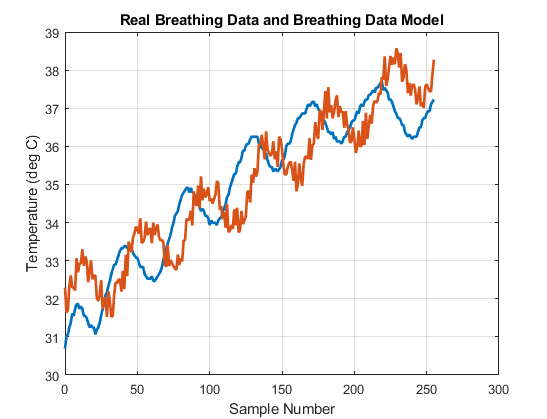

## **Section 2 – Fixed point data representation and scaling**

### **Section Description**

In this section you will use the breathing model that you created in section 1 and collect data in different ways to show how it can be represented as a float and a fixed point number even with a fractional portion.

Recall that floating point numbers can represent numbers with fractions.  Fixed point numbers can only represent integer values.  However, if we take a floating point number with a fractional portion we can scale that number by factors of 10 (1,10,100,1000) and then use a fixed point number to represent that fractional number as long as we keep track of the scale factor.

For example if we have a floating point number 33.4582 if that gets converted to a fixed point value it will be represented as 33.  If it is scaled by 10 first then converted to fixed point it will be 334 which represents the value 33.4 when scaled back down.  If it is scaled by 100 then converted to fixed point then the value is 3345 which represents 33.45 when scaled back down by 100.  In this way we can used fixed point numbers to represent fractional values.

When the conversion to a fixed point number is done, there is a rounding process that happens which leads to some amount of error or quantization noise.

When scaling the number we also have to be careful not to scale it so large that it cannot be represented properly in the fixed point number system we have chosen.

***Why fixed point?***

From Lab 5, you know that integer and long datatype computations are much faster than floating point computations.  Fixed point arithmetic enables integer storage of data by rescaling units to the finest precision value required for a problem, and then choosing an integer data type (`int `or `long`) to cover the required range.

*An illustration of the technique*

Temperature measurements in our system exhibit an SNR no better than about 30 dB (~32:1) for a 1 °C pk-pk amplitude sine wave temperature excursion, so there is no need to represent incremental temperatures less than 0.01°C or 1 centi-degree Celsius (cC).  Assume a working temperature range of -10 °C to +50 °C or -1000 cC to +5000 cC.  Then we can represent all meaningful temperatures with integer variables (INTs) with resolution of 1 cC.  For example, the floating point value 27.73 °C is stored as the integer 2773 cC.  Each sample measurement now requires just 2 bytes of memory for an INT instead of 4 bytes for a FLOAT, and computational speed is faster.

If the SNR of the sensor were 60 dB, we would choose a unit of 0.001C or 1 milli-degree Celsius (mC).  The operational range would be -10,000 mC to +50,000 mC, so a datatype of LONG variables would be required to store the number because they would exceed the range of an INT.  Each measurement value would require the same 4 bytes as it would if it were stored as a FLOAT, but speed would still be faster.

### Description of the code

For this section of the lab start with the code file in myCourses named "CodeBase_Lab06_Section2_2245.ino".

This code uses the model of the temperature sensor from section 1 with some modifications to the parameter values.

This code will return 4 values for each sample gathered.  The 1st column is the sample number.  The 2nd column is a floating-point number representing the temperature.  This is in the 2nd column and is the variable fltX in the C code.

The 3rd column is also a floating point number but it is the temperature value scaled by a constant in the code DATA_FXPT which will be set to 1, 10, 100 and 1000 respectively during the procedure.  The floating point temperature variable is called scaleFltX in the C code.

The 4th  column is a fixed point number that is the scaled floating point number converted to an integer value.  The conversion to fixed point rounds the value to the nearest integer which effectively adds quantization noise to the value.  The fixed point temperature variable is called fxptX in the C code

The 5th column of data is the difference between the scaled floating point number in column 3 and the fixed point value in column 4  

### **Procedure**

1. Modify the breathing temperature model parameters so that the signal has an average value of 33 °C (driftIntercept = 33.0),  no drift (driftSlope = 0.0), no noise (sigma = 0.0) and a breathing rate of 10 bpm with a magnitude of 0.6 °C peak.

2. Start with the value of DATA_FXPT set to 1.  Run the Arduino code and capture data in MATLAB using CaptureArduinoData.  Column 5 contains the error between the scaled fixed-point value and the scaled floating-point value.  Compute the standard deviation of the error.  This is the noise of the signal.  Calculate the signal level by computing the standard deviation of the scaled floating-point value in column 3.

Repeat the measurements for DATA_FXPT = 1, 10, 100, and 1000, respectively.  Complete a table of your results like the one shown below.  Include a short paragraph in your report interpreting your results.  An excel template of the table can be found in myCourses

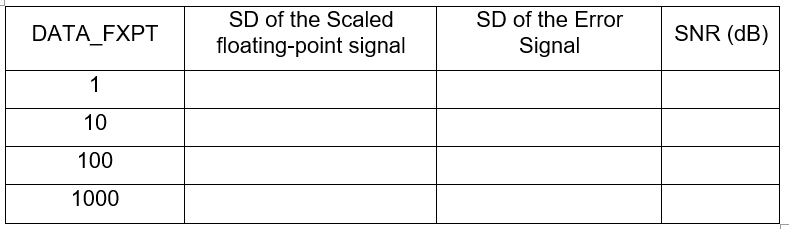

### **Table 1**

3. On the same graph plot the scaled floating point values and the scaled fixed point values for each value of the scale factor DATA_FXPT.  Also, create a plot with the quantization error for each value of DATA_FXPT to help your understanding.  Use a scatter plot for the error to display each individual point.  The error plots need not be included in your report.  A scatter plot can be drawn as in the example MATLAB code below.

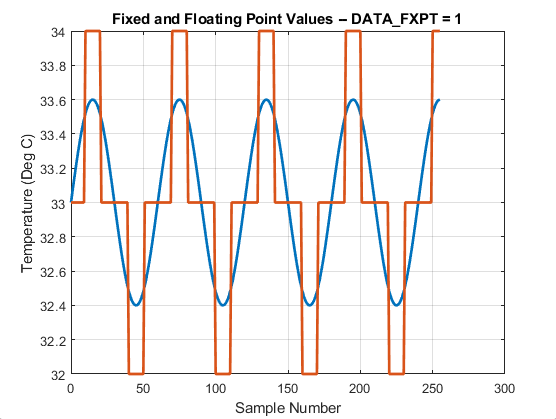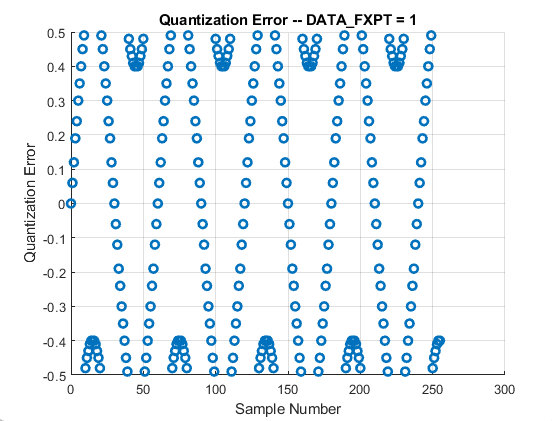

%  For each value of DATA_FXPT  Capture data in MATLAB, save the file and load 
%  the file.  Compute the standard deviation of the error and the standard deviation 
%  of the scaled floating point signal.  
%
%  Plot the scaled floating point value and the fixed point
%  value on the same graph for each value of DATA_FXPT
%
%  data = CaptureArduinoData('ComPort',7,'BaudRate',115200,'NumActivePlots',1)
%
%  Column 1 -- Sample Number
%  Column 2 -- Temperature (floating point)
%  Column 3 -- Temperature (scaled floating point)
%  Column 4 -- Temperature (scaled fixed point)
%  Column 5 -- Error (Column 3 - Column 4)


%  SOLUTION DATA_FXPT = 1




%  SOLUTION DATA_FXPT = 10



%  SOLUTION DATA_FXPT = 100


%  SOLUTION DATA_FXPT = 1000




## **Section 3 - FIR filtering with Moving Average Filter (MAV)**

### **Overview**

A moving average filter will be implemented to smooth out sensor noise.  Input/output data is represented in centi-degrees C by setting the value of DATA_FXPT = 100.  Observe the tradeoff of Moving Average Filter kernel length, noise suppression, and breathing signal attenuation.

Recall that a moving average filter has an impulse response that is a constant value for all samples.

### **Description of the code**

Copy the code "CodeBase_Lab06_Section3_2245.ino" into a new Arduino sketch.  In` setup(), `you can uncomment or comment out  functions to generate floating point coefficients for a Moving Average (MAV) or sinc FIR filter kernel as needed.

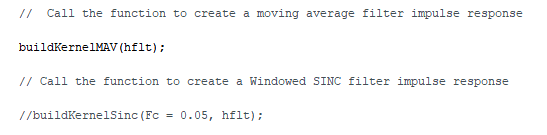

Coefficients of the filter kernel are displayed in the command window before data collection begins.  This can be enabled by uncommenting the call to the function "displayKernel".

In loop(), a fixed point temperature signal is simulated and convolved with the filter kernel.  The input and convolution output can be captured in MATLAB as fixed point integers.

### **Procedure**

1. When using the linear phase sinc kernel we need an odd number of elements so that the kernel is symmetric about the center sample.  The constant MFILT in the C Code is the number of kernel samples, so 0 is the lowest index and MFILT-1 is the highest index.  An even value of MFILT e.g.  MFILT = 6 (n = 0,1,2,3,4,5) is not symmetrical.  an odd value of MFILT, e.g. MFILT = 5 (n = 0,1,2,3,4) is symmetric about sample 2.  Set `MFILT` = 11 and begin by ucommenting the call to the function "`buildKernelMAV"` and commenting out the call to the function "`buildKernelSinc" `in `setup`().

2. Create a simulated breathing signal that exhibits zero drift (driftSlope = 0.0), 30 °C mean (driftIntercept = 30), 0.6 °C peak (tempP = 0.6) at 12 bpm, and 0.05 °C rms noise (sigma). Modify the variables in the simulatedBreathFxptDegC function.  Generate values in fixed point Celsius by setting the value of the constant DATA_FXPT = 100.  Recall that a temperature value of 33.45 will then be represented in fixed point number as 3345.

3. Run the code on the modeled temperature data.  Capture the values of the input to the filter (X) and the output of the filter (Y) in MATLAB using CaptureArduinoData.  The 1st column is the sample number, the 2nd column is the fixed point value of the input to the filter  (**fxptX**) and the 3rd column is the fixed point value of the output of the filer (**fxptY**).  Plot the input and the output of the filter (X and Y) on the same plot versus the sample number.  Add an appropriate title and axes labels.  Note that X and Y are not the X and Y axes but rather the two signals that you captured.

4. Observe the unusual filter output over the first 11 (MFILT) samples.  This is expected and corresponds to the number of cycles required to fill the data buffer used in the point-wise multiplication and addition operations of convolution.  We refer to these samples as the end effects of convolution.  To allow for better auto-scaling of graphs, replace the first MFILT elements of the output with the filter input values.  This can be done within the C code by uncommenting the line within the "floatKernelFIR" function.  The line is shown in the code below.

These first MFILT samples are equally meaningless as filter outputs, but they are convenient for make better plots.  You may Ignore these values.

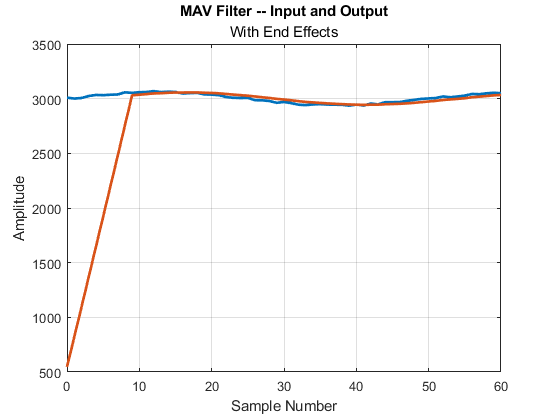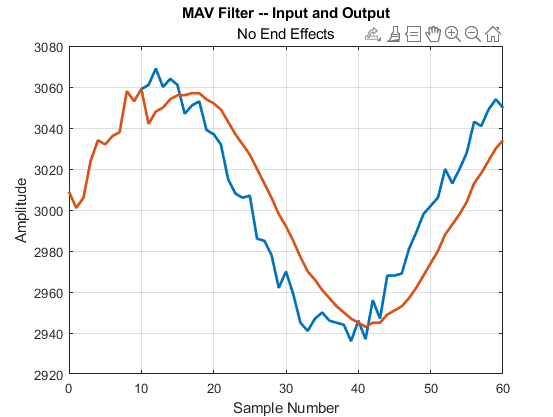

4. Plot the input to the filter and the output of the filter on the same plot for each case of MFILT = 11 and MFILT = 41.  Write a short paragraph describing the impact of kernel length on the number of valid output samples and on output signal and noise amplitudes relative to the corresponding input signal components.

%
%  Load the file with the MAV filter input and filter output for MFILT = 11
%
%  Plot the result with end effects included
%
%

%  SOLUTION




%
%  Plot the result without end effects included
%
%

%  SOLUTION



%
%  Load the file with the MAV filter input and filter output for MFILT = 41
%
%  Plot the result without the end effects included
%
%

%  SOLUTION





## **Section 4 - FIR filtering with Windowed Sinc Filter**

### **Overview**

The filtering of the breathing samples can be improved by using a windowed sinc filter kernel, which is better at isolating and attenuating high frequencies than the moving average filter.

### **Procedure**

Use the same code as in Section 3

1. Comment out the `buildKernelMAV()` function call in `setup()` and uncomment the call to the `buildKernelSinc() function`.  Set Fc = 0.05 as the argument to the function.  Fc is the corner frequency of the filter expressed as a fraction of the sampling frequency.  The sampling period is 100 msec, corresponding to a sampling frequency of 10 Hz.  Compute the normalized corner frequency by dividing the desired corner frequency by the sampling frequency.

### 
$$F_{c(norm)}=\frac{F_c}{F_s }$$


To set the filter corner to match a specific breathing rate (bpm), convert the breathing rate in breaths per minute to breaths per second and divide by the sampling frequency.

### 
$$F_{c_{norm}}=\frac{bpm(\frac{1}{60}\frac{min}{sec})}{F_s}$$


As an example, to set the corner frequency to match 30 breaths per minute set the variable $F_c$ as

### 
$$F_c = \frac{(30)(\frac{1}{60})}{10 Hz}=0.05$$


2. Set the length of the impulse response using MFILT = 11 and run the code on the same simulated breathing signal as you used for the moving average filter (MAV).  

3. Capture the input and output data from the filter in MATLAB. Note the sum of the kernel samples reported after sample enumeration.  This can be seen at the top of the command window before the input and output data is displayed.  

4. Plot the input and output samples.  What is the DC gain of the system for samples beyond the first MFILT samples?  The gain is the ratio of the filter output to the input signal.

%  Plot the results of filtering with the Windowed SINC filter for length
%  MFILT = 11.  

% SOLUTION


5. The DC gain of a FIR filter is the output of the filter for input samples that are all 1.  It can be found by summing all the values of the impulse response.  To normalize the filter gain to 1 the impulse response is scaled by 1 divided by the sum of the impulse response values.  The sum of the impulse response values is found at the top of the output in the command window before the impulse reponse is printed.

6. Modify the `buildKernelSinc`() function to generate DC gain = 1.0 for any MFILT in the code section below.  this is done by computing the sum of the impulse response and dividing each value of the impulse response by the sum.

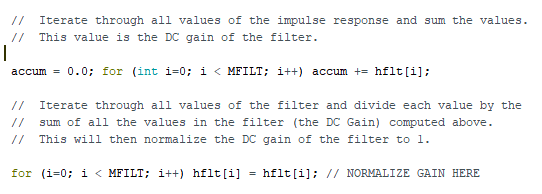

7. After setting the filter DC gain to 1.0, plot the filter input and the filter output on the same graph for each case of MFILT = 11 and MFILT = 41.  Write a short paragraph describing the impact of kernel length on the number of valid output samples and on the output signal and noise amplitudes relative to the input signal components.

%  Plot the results of filtering with the Windowed SINC filter for length
%  MFILT = 11 and 41 with the DC gain set to 1.0

% SOLUTION



## **Section 5 – Fixed Point FIR Filter Convolution**

### **Overview**

In Lab 5 you documented the speed advantages of integer over floating point math.  In this section, you will convert the filter kernel from floating point values to fixed-point integers and investigate the speed consequences of fixed point implementation choices.

Copy the code in file "CodeBase_Lab06_Section5_2245.ino" from myCourses and paste it into a new Arduino sketch.

In` setup(),`a sinc kernel is computed in floating point for a specified kernel length, MFILT.  To create a fixed point kernel it is then scaled by HFXPT.  This creates an impulse response using fixed point values that are integers  similar to the way that the floating point temperature data was scaled to create a fixed point integer.  The floating point kernel is also scaled by HFXPT so that the two filters have the same gain.  The scale factor for each impulse response is HFXPT.

The floating point, scaled floating point, and the fixed point SINC filter impulse response coefficients are displayed to the command window along with the sum of the impulse responses.  When a unity gain kernel is expressed in fixed point, its DC gain is HFXPT because of the scaling.

The simulated breathing signal is the input to the filter.  It is also converted to a fixed point value by scaling it by a value DFXPT (for data Fixed Point).  This fixed point input is convolved with the fixed point filter kernel.  The input and the output of the filter are displayed in the console as fixed point integers.

#### Fixed Point Convolution Discussion

Recall that the convolution sum generates each output point as the sum of products of current and past input samples with N = MFILT kernel elements.

### 
$$y[n]=\sum_{i=0}^{N-1}h[i]x[n-i]$$


When we express the filter input X[n] in fixed point notation by scaling with DFXPT, the output of the filter Y[n] is also scaled by the same value, DFXPT.  We can recover the original scaling of the signal by dividing the filter output by DFXPT if we choose, though generally we do so only for display.  

### 
$$DFXPT*y[n]=\sum_{i=0}^{N-1}h[i](DFXPT*x[n-i])$$


### 
$$y_{fxd}[n] = \sum_{i=0}^{N-1}h[i]x_{fxd}[n-1]$$


When we express the filter impulse response h[n] in fixed point by scaling with HFXPT, the filter output y[n] is also scaled by HFXPT.   To scale the filter output correctly it must be divided by the HFXPT scale value.

#### 
$$HFXPT*y_{fxd}[n]=\sum_{i=0}^{N-1}(HFXPT*h[i])x_{fxd}[n-i]$$


#### 
$$y_{fxd}[n]=(1/HFXPT)\sum_{i=0}^{N-1}h_{fxh}[i]x_{fxd}[n-i]$$


Division is slow, so the 1/HFXPT scale factor is computed ahead of time at compile time and implemented through multiplication.

During the computation of the convolution output the input samples X[n] are multiplied by the impulse response values h[n] and the result of the multiplication is accumulated.  Because both h[n] and X[n] are 16 bit datatypes, their product is a 32 bit datatype.  We need to provide a large enough data type for the accumulated values.

We do this by temporarily casting either h[ ] or X[ ] to a datatype with adequate range to handle the worst case accumulation.  The compiler will automatically cast the other element to the same type when doing arithmetic. The fastest assignment that can be made for a given data type is to a variable of the same type, so we should always make the temporary cast to the same type as the accumulator variable.  Our two choices are `float` and `long`.

This is demonstrated in the C-code below

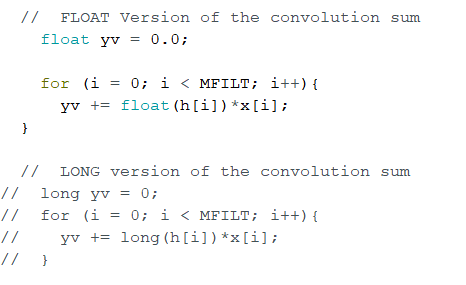

### **Procedure**

1. Set MFILT = 41, Fc = 0.05, DATA_FXPT = 100, HFXPT = 100, and run the code on the same modeled temperature as in the previous section.  Note the sum of kernel samples reported at the top of the command window output.

Note that some of the values of the fixed point filter kernel are zero due to rounding of the floating point values.  Why does this occur?

If we constrain HFXPT to be a power of 2, what is the minimum value that guarantees each value of the fixed point kernal are >=1 for all non-zero elements of hflt?  That is, what value would I have to multiply the smallest kernel value by to guarantee that it is greater than or equal to +/-1?

%  Look at the values of the kernel printed in the command window.
%  Find the minimum non-zero value of the floating point kernel values (hflt).
%  Find the minimum power of 2 (i.e. 2^X) that is required
%  to keep the value in the kernel greater than or equal to 1

% SOLUTION

min_hflt_Value = 0.000442

min_hflt_Value = 4.4200e-04

power2 = log2(1/min_hflt_Value)

power2 = 11.1437

HFXPT = 2^ceil(power2)

HFXPT = 4096


%  Verify that your value for HFXPT is correct.  Set the value of HFXPT in
%  the C code to the value you computed.  Re-run the code and verify that
%  the smallest fixed point impulse response value is greater than or equal to +/- 1




2. For DATA_FXPT = 100, MFILT = 41, and HFXPT from step 1, what is the maximum value of the fixed point convolution sum (prior to division by HFXPT) for a 50 °C DC input?  Confirm your estimate by simulating breathing around a 50 C mean.  Set the mean value by setting the drift intercept in the model to 50.  Then find the maximum value of the accumulator by multiplying the output by the scale factor  HFXPT.  Can this value be represented as a float?  Can this value be represented as a long?

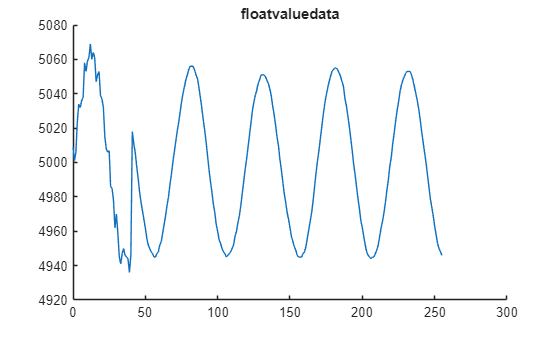

%  With the mean value of temperature set to 50 find the maximum value of
%  the accumulator by finding the maximum value of the output of the filter
%  and multiplying by HFXPT from step 1.

%  SOLUTION

file = load("section5part2new50.mat");
data = file.outData;


figure;
hold on;
plot(data(:,1),data(:,3))


title("floatvaluedata")

3.  Compare the results when using a float or a long accumulator by commenting out one version of the convolution sum and uncommenting the other version as shown below.

Write a short paragraph justifying your choice of `float` or `long` accumulation for a fixed point convolution implementation of our system.  Discuss precision and range requirements.  Include speed measurements for both choices.

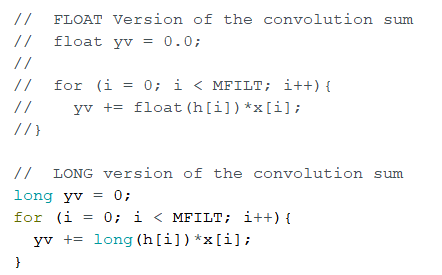

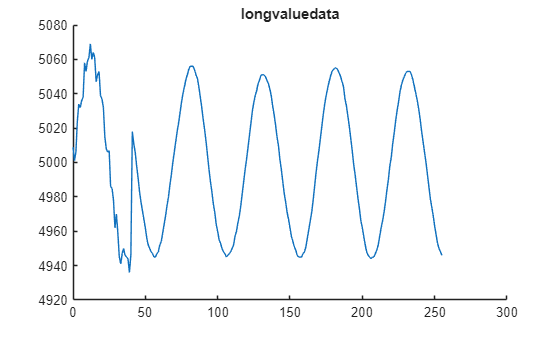

%  Compare the results of using a long or a float for the accumulator.
%  Plot both results and compare the execution speeds

%  SOLUTION

file = load("longdata.mat");
data = file.outData;


figure;
hold on;
plot(data(:,1),data(:,3))


title("longvaluedata")

4. Plot fxptX and fxptY on common axes for MFILT = 41. Plot the difference between the outputs for the floating point and fixed point kernel implementations for both accumulator types (FLOAT and LONG).  For each accumulator type, consider the floating point SINC filter output as the ‘gold standard’ signal.  The error is the difference of each output and the ‘gold standard’.  Plot the error between the filter types.

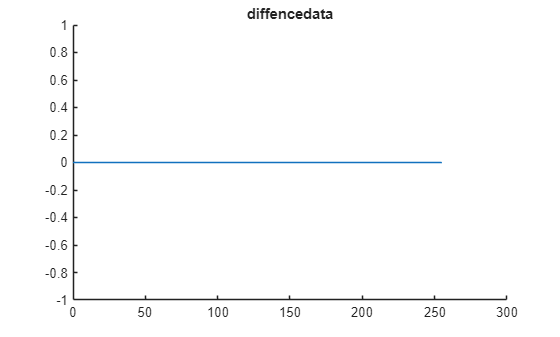

%  Plot the error between the LONG and FLOAT accumulator implementations.
%



%  SOLUTION

file = load("section5part2new50.mat");
data = file.outData;
file = load("longdata.mat");
longdata = file.outData;

figure;
hold on;
sample= data(:,1) ;
indatat= data(:,3);
outdata = longdata(:,3);

differnce= outdata - indatat;
plot(sample,differnce)

title("diffencedata")

### **Write up**

Lab 6 addresses four major issues.  Your write up should demonstrate understanding and serve as a high-level tutorial for all four.  Use the IEEE report format.  The following is a guide.

- Signal conditioning and modeling.  Show an overlay plot of `float` samples of LM61 measured breathing and modeled breathing, scaled in degrees Celsius.  Show a code snippet of the model with your parameters applied.  Include a short paragraph describing model operation.

- Fixed point data representation.  Write a short paragraph describing the choice of fixed point scaling (scale factor DATA_FXPT 1, 10, 100, 100) mC) and integer type (`int`, `lon`g) for the breathing temperature problem.  Show charts of modeled breathing data comparing scaled float and fixed point representations for scale values  DATA_FXPT of 100 and 1000. Explain the problem with DATA_FXPT = 1000 and how DATA_FXPT = 100 is acceptable in terms of assumed data range and precision.

- Compare MAV and SINC filter performance.  Show plots of MAV and sinc filtered model data for filter kernel lengths 11 and 41 (4 charts all together).  Comment on the relative merits of MAV versus LPF sinc filtering for improving the SNR of the raw breathing signal (signal in vs. out, noise in vs. out).

- Fixed point FIR filter implementation.  Justify your choice of sinc kernel fixed point (HFXPT) in terms of minimum kernel element size for the MFILT = 41 case. Justify your choice of convolution accumulator variable type in terms of kernel DC gain and maximum input signal amplitude.  Use a table to report the per-point execution times of the MFILT = 41 sinc filter using a floating point kernel, a fixed point kernel with a `float` typed accumulator, and a fixed point kernel with a `long` typed accumulator.  Show plots comparing filter outputs when processing modeled breathing data for your float and fixed point kernel designs.

### Lab Report Rubric